M = 29;
omega_c = 1.5708;
beta = 6;
M1 = M

M1 = 29

M2 = M+round(M/2)

M2 = 44

M3 = 2*M

M3 = 58

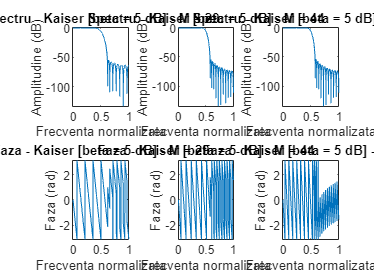


win11 = kaiser(M1,beta-1);
win12 = kaiser(M2,beta-1);
win13 = kaiser(M3,beta-1);

win91 = blackman(M1);
win92 = blackman(M2);
win93 = blackman(M3);

f11 = fir1(M1-1,freq_c,win11);
f12 = fir1(M2-1,freq_c,win12);
f13 = fir1(M3-1,freq_c,win13);

f91 = fir1(M1-1,freq_c,win91);
f92 = fir1(M2-1,freq_c,win92);
f93 = fir1(M3-1,freq_c,win93);

[h11,w11] = freqz(f11,1,K);
[h12,w12] = freqz(f12,1,K);
[h13,w13] = freqz(f13,1,K);

[h91,w91] = freqz(f91,1,K);
[h92,w92] = freqz(f92,1,K);
[h93,w93] = freqz(f93,1,K);

%Figura 14
figure;
subplot(2,3,1);
plot(w11/pi,20*log10(abs(h11)));
title('Spectru - Kaiser [beta = 5 dB] - M = 29');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,2);
plot(w12/pi,20*log10(abs(h12)));
title('Spectru - Kaiser [beta = 5 dB] - M = 44');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,3);
plot(w12/pi,20*log10(abs(h12)));
title('Spectru - Kaiser [beta = 5 dB] - M = 58');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,4);
plot(w11/pi,angle(h11));
title('Faza - Kaiser [beta = 5 dB] - M = 29');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,3,5);
plot(w12/pi,angle(h12));
title('Faza - Kaiser [beta = 5 dB] - M = 44');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,3,6);
plot(w13/pi,angle(h13));
title('Faza - Kaiser [beta = 5 dB] - M = 58');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

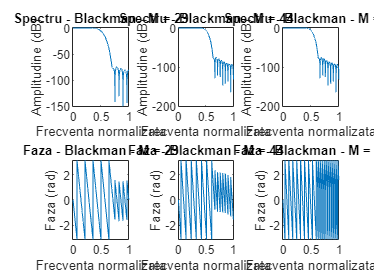


%Figura 15
figure;
subplot(2,3,1);
plot(w91/pi,20*log10(abs(h91)));
title('Spectru - Blackman - M = 29');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,2);
plot(w92/pi,20*log10(abs(h92)));
title('Spectru - Blackman - M = 44');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,3);
plot(w92/pi,20*log10(abs(h92)));
title('Spectru - Blackman - M = 58');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,3,4);
plot(w91/pi,angle(h91));
title('Faza - Blackman - M = 29');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,3,5);
plot(w92/pi,angle(h92));
title('Faza - Blackman - M = 44');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,3,6);
plot(w93/pi,angle(h93));
title('Faza - Blackman - M = 58');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');